clc; clear; close all;
mkdir('outputs'); % çıktı klasörü 

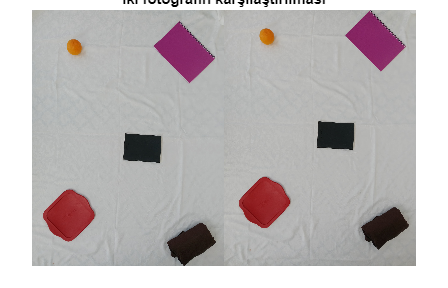

org_img = iread('or_img.jpeg', 'uint8'); % matrixleri görmemek için "%" kullandım
shif_img = iread('shif_img.jpeg', 'uint8');
imshowpair(org_img, shif_img,"montage");title("iki fotoğrafın karşılaştırılması")

s1 = size(org_img) % [4080x3060x3]

s1 =         4080        3060           3


s2 = size(shif_img)% [4080,3060,3]

s2 =         4080        3060           3


Histogram ve Grey okuma & Adjust etme

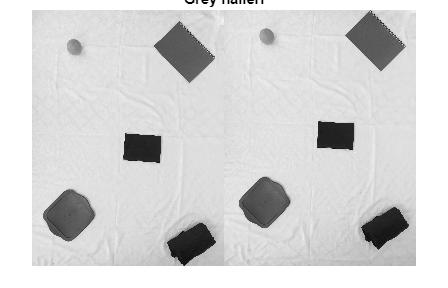

org_img_grey = iread('or_img.jpeg', 'uint8', 'grey'); % matrixleri görmemek için "%" kullandım
shif_img_grey = iread('shif_img.jpeg', 'uint8', 'grey');
imshowpair(org_img_grey, shif_img_grey, "montage");title("Grey halleri")

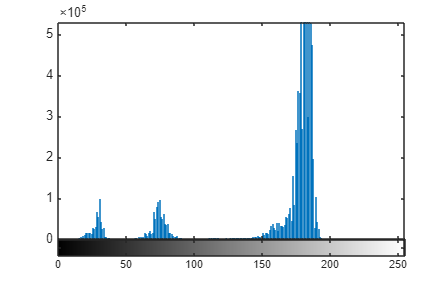


%Orijinal image'yi adjust etme ve histogramına bakma
imhist(org_img_grey)

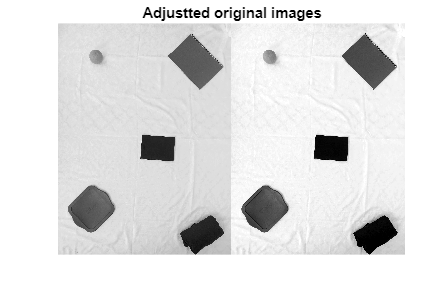

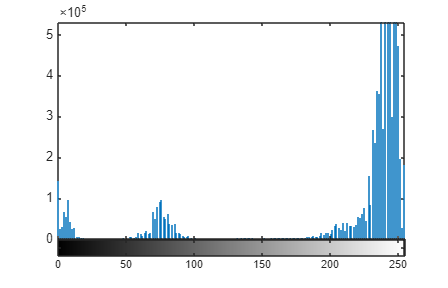

org_img_greyAdj = imadjust(org_img_grey);
imshowpair(org_img_grey, org_img_greyAdj, "montage")
title("Adjustted original images");imhist(org_img_greyAdj)

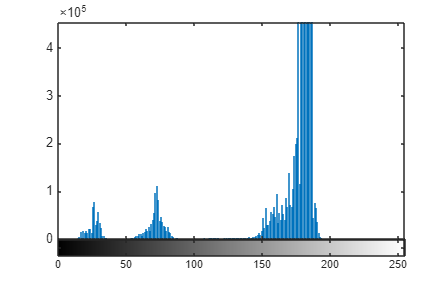


%Shifted image'yi adjust etme ve histogramına bakma
imhist(shif_img_grey)

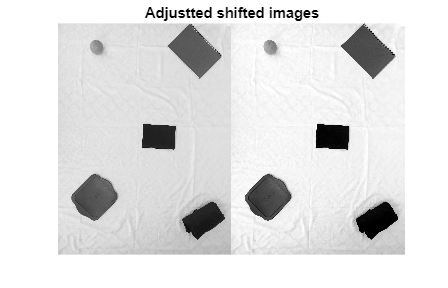

shif_img_greyAdj = imadjust(shif_img_grey);
imshowpair(shif_img_grey, shif_img_greyAdj, "montage");title("Adjustted shifted images")

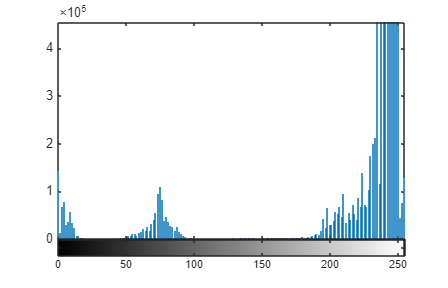

imhist(shif_img_greyAdj)

Histogramın analizi belli bir aralığı alma

%imageViewer

Negative alma

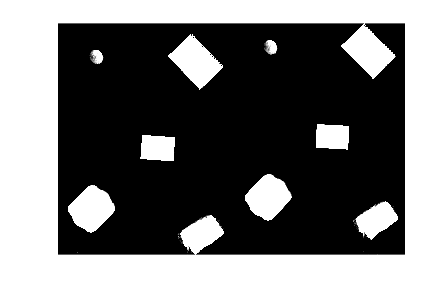

im1 = uint8(255) - imageViewer_or; % maskeleme işlemi yaparken logic seviyesinde 
% beyazları 1 siyahları 0 kabul etmek için reverse aldım. imcomplement()
% diye de bir fonksiyon varmış onu sonradan öğrendim.
im2 = uint8(255) - imageViewer_shif;
%şöyle de olurdu im2= ~imageViewer_shift_img_greyAdj

imshowpair(im1, im2, "montage")

Filtreleme ve Morfolojik İşlemler

filter2 = fspecial("average", 3)% average 3x3

filter2 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111



%filtreleme
org_clean = imfilter(im1, filter2);
shif_clean = imfilter(im2, filter2);
imshowpair(im1, org_clean, "montage")
imshowpair(im2, shif_clean, "montage")

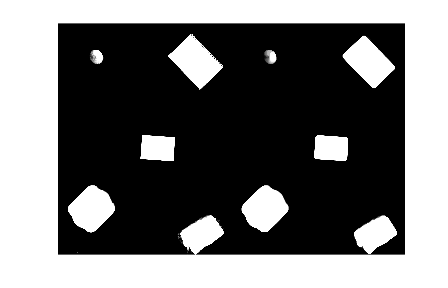

%erosion
erosion = strel("disk", 50); % bu kadar büyük genişlikte seçmemin sebebi kumaşın kenarlarını
%birer obje olarak ele alması
c1 = imopen(org_clean, erosion);
c2 = imopen(shif_clean, erosion);
imshowpair(org_clean, c1, "montage")

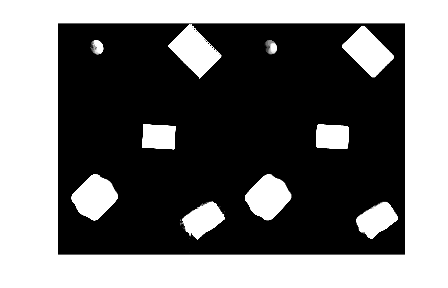

imshowpair(shif_clean, c2, "montage")

Edge'leri bulma

% % Sadece kontur (kenar) piksellerini al
% edges1 = bwperim(c1);
% edges2 = bwperim(c2);
% 
% imshowpair(edges1,edges2, "montage"); title('Sağ-Sol Binary Maske Kenarları');

Bounding box ve Centroid çizimi

% % Orijinal için
% props_edge = regionprops(edges1, 'Centroid', 'BoundingBox');
% figure; imshow(c1); hold on; title('Orijinal');
% 
% for i = 1:length(props_edge)
% rectangle('Position', props_edge(i).BoundingBox, 'EdgeColor', 'r','LineWidth', 1.5);
% plot(props_edge(i).Centroid(1), props_edge(i).Centroid(2), 'o');
% end
% 
% % Shifted için
% props_edge1 = regionprops(edges2, 'Centroid', 'BoundingBox');
% figure; imshow(c2); hold on; title('Shifted');
% 
% for j = 1:length(props_edge1)
% rectangle('Position', props_edge1(j).BoundingBox, 'EdgeColor', 'r','LineWidth', 1.5);
% plot(props_edge1(j).Centroid(1), props_edge1(j).Centroid(2), 'o');
% end

left_cc = bwconncomp(c1);%finds and counts the connected components CC in the binary image BW.
right_cc = bwconncomp(c2);%finds and counts the connected components CC in the binary image BW.

% Orijinal görüntü için çizim
left_stats = regionprops(left_cc, 'BoundingBox', 'Centroid', 'Area');
figure; imshow(c1); hold on;
for i = 1:length(left_stats)
    bbox = left_stats(i).BoundingBox;
    centroid = left_stats(i).Centroid;
    rectangle('Position', bbox, 'EdgeColor', 'r', 'LineWidth', 2);
    plot(centroid(1), centroid(2), 'g+', 'MarkerSize', 10);
end
title('Orijinal Kamera: Nesne Tespiti');

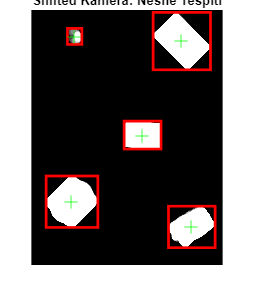



% Shifted görüntü için çizim (aynı işlemler)
right_stats = regionprops(right_cc, 'BoundingBox', 'Centroid', 'Area');
figure; imshow(c2); hold on;
for i = 1:length(right_stats)
    bbox = right_stats(i).BoundingBox;
    centroid = right_stats(i).Centroid;
    rectangle('Position', bbox, 'EdgeColor', 'r', 'LineWidth', 2);
    plot(centroid(1), centroid(2), 'g+', 'MarkerSize', 10);
end
title('Shifted Kamera: Nesne Tespiti');

Elips ve dair özelliklerini edinme

% Dosya oluştur
fid = fopen('outputs/elips_alan_ozellikleri.txt', 'w');

% Orijinal görüntü üzerine çizim ve hesaplama
figure; imshow(c1); hold on;
for i = 1:length(left_stats)
    centroid = left_stats(i).Centroid;
    area = left_stats(i).Area;
    stats_ellipse = regionprops(left_cc, 'Orientation', 'MajorAxisLength', 'MinorAxisLength');
    
    % Elips parametreleri
    a = stats_ellipse(i).MajorAxisLength / 2;
    b = stats_ellipse(i).MinorAxisLength / 2;
    theta = deg2rad(-stats_ellipse(i).Orientation);
    t = linspace(0, 2*pi, 100);
    x = a * cos(t);
    y = b * sin(t);
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    ellipse = R * [x; y];
    plot(centroid(1) + ellipse(1,:), centroid(2) + ellipse(2,:), 'g', 'LineWidth', 1.5);
    
    % Alan ve elips bilgilerini yaz
    fprintf(fid, 'Obje %d:\n', i);
    fprintf(fid, ' - Alan: %.2f px^2\n', area);
    fprintf(fid, ' - MajorAxis: %.2f px\n', 2*a);
    fprintf(fid, ' - MinorAxis: %.2f px\n', 2*b);
    fprintf(fid, ' - Orientation: %.2f derece\n\n', -theta * (180/pi));
end
title('Elipsler ve Alan Özellikleri');
saveas(gcf, 'outputs/original_ellipses.png');
fclose(fid);

% Her objenin centroid farkını hesapla
fid = fopen('outputs/centroid_disparity.txt', 'w');
disparities = zeros(length(left_stats), 1);

for i = 1:length(left_stats)
    xL = left_stats(i).Centroid(1);
    xR = right_stats(i).Centroid(1);
    disparities(i) = abs(xL - xR);
    fprintf(fid, 'Obje %d - Piksel Kaymasi (Disparity): %.2f px\n', i, disparities(i));
end
fclose(fid);

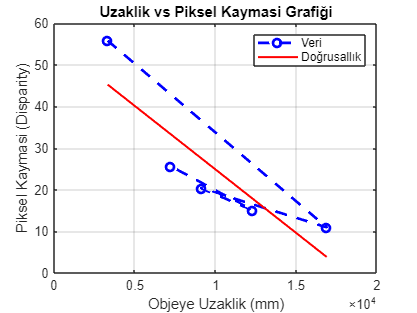

% Parametreler
f = 4.15;       % mm
B = 50;         % mm
p = 0.00112;    % mm/pixel

% Uzaklık hesapla
depths = (f * B) ./ (disparities * p);

% Grafik çiz
figure;
plot(depths, disparities, 'bo--', 'LineWidth', 2); hold on;
xlabel('Objeye Uzaklik (mm)');
ylabel('Piksel Kaymasi (Disparity)');
title('Uzaklık vs Piksel Kaymasi Grafiği');
grid on;

% Regresyon çizgisi
pfit = polyfit(depths, disparities, 1);
plot(depths, polyval(pfit, depths), 'r-', 'LineWidth', 1.5);
legend('Veri', 'Doğrusallık');
saveas(gcf, 'outputs/graph_depth_vs_disparity.png');